De volgende parameters moeten instelbaar zijn:

- estimatedLayerThickness

- filepath

- maxDistanceToPlane

clear;clc;clf;
close all

The following function reads in the image and stores it in pointcloud

[`ptCloud`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcread.html?searchHighlight=pcread&s_tid=doc_srchtitle#buphpf3-1-ptCloud) `=` `pcread``(`[`filename`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcread.html?searchHighlight=pcread&s_tid=doc_srchtitle#buphpf3-1-filename)`)` reads a point cloud from the PLY or PCD file specified by the input `filename`. The function returns a [`pointCloud`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.html) object, `ptCloud`.

File name, specified as a character vector or a string scalar. The input file type must be a PLY or a PCD format file.

The polygon (PLY) file format , also known as the Stanford triangle format stores three-dimensional data from 3-D scanners. It is a format for storing graphical objects that are described as a collection of polygons. A PLY file consists of a header, followed by a list of vertices and then, a list of polygons. The header specifies how many vertices and polygons are in the file. It also states what properties are associated with each vertex, such as (*x*,*y*,*z*) coordinates, normals, and color. The file format has two sub-formats: an ASCII representation and a binary version for compact storage and for rapid saving and loading. The header of both ASCII and binary files is ASCII text. Only the numeric data that follows the header is different between the two versions. See [The PLY Format](https://www.mathworks.com/help/releases/R2023b/vision/ug/the-ply-format.html) for details on the contents of a PLY file.

The point cloud data (PCD) file format also stores three-dimensional data. It was created by the authors of the widely used point cloud library (PCL) to accommodate additional point cloud data requirements. See [The PCD (Point Cloud Data) file format](https://pointclouds.org/documentation/tutorials/pcd_file_format.html#).

ptCloud = Object for storing point cloud, returned as a [`pointCloud`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.html) object that contains the following PLY or PCD fields:

- `Location` property, stores the *x*, *y*, and *z* values.

- `Color` property, stores the red, green, and blue values.

- `Normal` property, stores the normal vectors for each point.

- `Intensity` property, stores the grayscale intensity for each point.

filepath = 'LAI_detection\LC_20231130_152650.ply';
pointcloud = pcread(filepath);

% clean up the pointcloud by setting the distance to an overestimation of the approximate distance to the wall
% such that only actual outliers are removed
maxDistanceToPlane = 1;
[model,inlierIndices, outlierIndices] = pcfitplane(pointcloud,maxDistanceToPlane);

[`model`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcfitplane.html?searchHighlight=pcfitplane&s_tid=doc_srchtitle#busqbp7-1-model) `=` `pcfitplane``(`[`ptCloudIn`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcfitplane.html?searchHighlight=pcfitplane&s_tid=doc_srchtitle#busqbp7-1-ptCloudIn)`,`[`maxDistance`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcfitplane.html?searchHighlight=pcfitplane&s_tid=doc_srchtitle#busqbp7-1-maxDistance)`)` fits a plane to a point cloud that has a maximum allowable distance from an inlier point to the plane. The function returns a geometrical model that describes the plane.

This function uses the M-estimator SAmple Consensus (MSAC) algorithm to find the plane. The MSAC algorithm is a variant of the RANdom SAmple Consensus (RANSAC) algorithm.

`[`[`model`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcfitplane.html?searchHighlight=pcfitplane&s_tid=doc_srchtitle#busqbp7-1-model)`,`[`inlierIndices`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcfitplane.html?searchHighlight=pcfitplane&s_tid=doc_srchtitle#busqbp7-1-inlierIndices)`,`[`outlierIndices`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pcfitplane.html?searchHighlight=pcfitplane&s_tid=doc_srchtitle#busqbp7-1-outlierIndices)`] =` `pcfitplane``(``___``)` additionally returns the linear indices to the inlier and outlier points in the point cloud input.

[https://en.wikipedia.org/wiki/Random_sample_consensus](https://en.wikipedia.org/wiki/Random_sample_consensus)

pcfitplane(pointcloud,1) zorgt er eigenlijk voor dat er een "gemiddelde" vlak door de punten gaat, vgl met PCA rechte uit 3-Wiskunde. Dan gaat het alle punten die binnen 1 meter van het vlak plaatsen in de "inlierIndices". Al de rest (in dit geval zijn het de uitschieters, verkeerde metingen) plaats die in de outlierIndices.

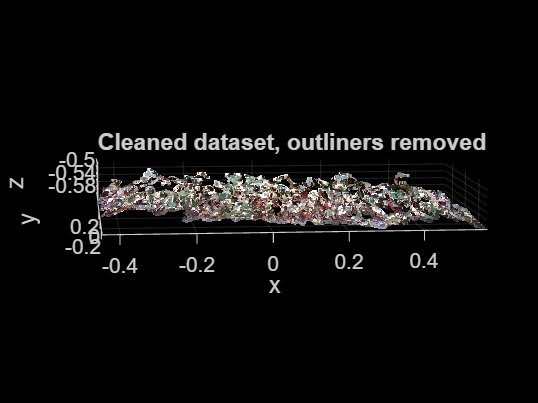

cleancloud = select(pointcloud, inlierIndices); % Deze dataset is degene die we moeten gebruiken
pcshow(cleancloud)
title("Cleaned dataset, outliners removed")
xlabel("x");
ylabel("y");
zlabel("z");

[`ptCloudOut`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.select.html?searchHighlight=select&s_tid=doc_srchtitle#mw_42763d17-153d-4d09-bc72-4b7ea802f6b3) `=` `select``(`[`ptCloud`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.select.html?searchHighlight=select&s_tid=doc_srchtitle#mw_6db4c8de-87bc-400e-8763-47cebef024fb)`,`[`indices`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.select.html?searchHighlight=select&s_tid=doc_srchtitle#mw_7b78b761-d0f7-4973-97d2-96a7f474f27a)`)` returns a [`pointCloud`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.html) object containing only the points that are selected using linear or logical indices.

cleancloud, returned as a [`pointCloud`](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.html) object.

The `pointCloud` object creates point cloud data from a set of points in 3-D coordinate system. The points generally represent the *x*,*y*, and *z* geometric coordinates for samples on a surface or of an environment. Each point can also be represented with additional information, such as the RGB color. The point cloud data is stored as an object with the properties listed in [Properties](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.html#mw_f3ba7640-4f89-4b79-b75b-51a71cd2c743). Use [Object Functions](https://www.mathworks.com/help/releases/R2023b/vision/ref/pointcloud.html#mw_06b93a3b-b53a-4e1f-9e52-eaa29dec0361) to retrieve, select, and remove desired points from the point cloud data.

disp(cleancloud.ZLimits) % returns the minimal and maximal value in the Z direction.

   -0.5850   -0.4636



diepte = abs(cleancloud.ZLimits(1) - cleancloud.ZLimits(2)); % Dit geeft de absolute waarde van de diepte weer.
breedte = abs(cleancloud.XLimits(1)-cleancloud.XLimits(2));
hoogte = abs(cleancloud.YLimits(1)-cleancloud.YLimits(2));
disp(mean(cleancloud.Normal))

    0.0128    0.0838    0.7776



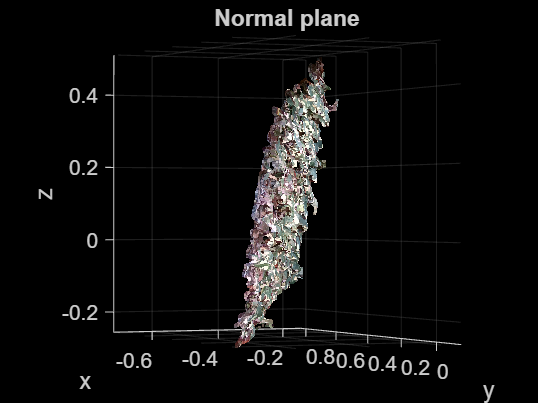

tform = normalRotation(model,[0 0 1]);
cleancloud = pctransform(cleancloud,tform);
pcshow(cleancloud)
title("Normal plane")
xlabel("x");
ylabel("y");
zlabel("z");

Nu hebben we een schatting van de dikte van de leaves nodig om heel de bladerdek te kunnen indelen in schijven.

estimatedLayerThickness = 0.01;

De volgende code gaat nu terug een plane fitten in de data, maar deze keer enkel alle punten die 0.01 (=estimatedLayerThickness) meter van elkaar verwijderd zijn. 

aantalLayers = round(diepte/estimatedLayerThickness)

aantalLayers = single
12

% for i=1:aantalLayers
%     [model,inlierIndices, outlierIndices] = pcfitplane(cleancloud,estimatedLayerThickness*i);
%     layer = select(cleancloud, inlierIndices);
%     figure();pcshow(layer)
%     title("Leaves layer "+i)
% end 
oppervlakte_beeld = breedte*hoogte;
aantalLayers2 = diepte/oppervlakte_beeld

aantalLayers2 = single
0.1863